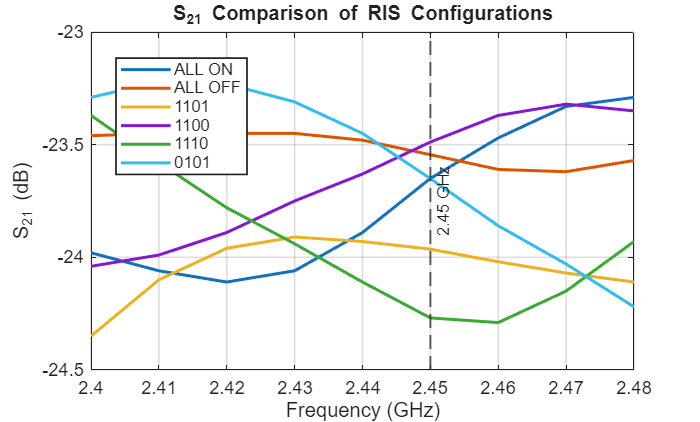

clc;
clear;
close all;

%% ============================================================
%  S21 COMPARISON OF DIFFERENT RIS CONFIGURATIONS
%
%  TX-RX Distance = 25.6 cm
%  Frequency Range = 2.40 GHz to 2.48 GHz
%
%  Data obtained from the S21 curves in the Ansys plots
% =============================================================

%% Frequency points
freq = 2.40:0.01:2.48;       % GHz

%% ============================================================
% S21 data in dB
% ============================================================

% ALL ON
S21_ALL_ON = [
    -23.98
    -24.06
    -24.11
    -24.06
    -23.89
    -23.65
    -23.47
    -23.33
    -23.29
];

% ALL OFF
S21_ALL_OFF = [
    -23.46
    -23.45
    -23.45
    -23.45
    -23.48
    -23.5445
    -23.61
    -23.62
    -23.57
];

% 1101
S21_1101 = [
    -24.35
    -24.10
    -23.96
    -23.91
    -23.93
    -23.9639
    -24.02
    -24.07
    -24.11
];

% 1100
S21_1100 = [
    -24.04
    -23.99
    -23.89
    -23.75
    -23.63
    -23.4884
    -23.37
    -23.32
    -23.35
];

% 1110
S21_1110 = [
    -23.37
    -23.58
    -23.78
    -23.94
    -24.11
    -24.2693
    -24.29
    -24.15
    -23.93
];

% 0101
S21_0101 = [
    -23.29
    -23.22
    -23.23
    -23.31
    -23.45
    -23.6507
    -23.86
    -24.03
    -24.22
];


%% ============================================================
% Plot
% ============================================================

figure('Color','w');

plot(freq, S21_ALL_ON,'LineWidth', 1.8, ...
    'MarkerSize', 5);
hold on;

plot(freq, S21_ALL_OFF,'LineWidth', 1.8, ...
    'MarkerSize', 5);

plot(freq, S21_1101, 'LineWidth', 1.8, ...
    'MarkerSize', 5);

plot(freq, S21_1100, 'LineWidth', 1.8, ...
    'MarkerSize', 5);

plot(freq, S21_1110,'LineWidth', 1.8, ...
    'MarkerSize', 5);

plot(freq, S21_0101, 'LineWidth', 1.8, ...
    'MarkerSize', 5);

%% 2.45 GHz reference line
xline(2.45, '--', '2.45 GHz', ...
    'LineWidth', 1.2, ...
    'LabelVerticalAlignment', 'middle');

%% Formatting
grid on;
box on;

xlabel('Frequency (GHz)');
ylabel('S_{21} (dB)');

title('S_{21} Comparison of RIS Configurations');

xlim([2.40 2.48]);

ylim([-24.5 -23.0]);

xticks(2.40:0.01:2.48);

legend( ...
    'ALL ON', ...
    'ALL OFF', ...
    '1101', ...
    '1100', ...
    '1110', ...
    '0101', ...
    'Location','best');

set(gca, ...
    'FontSize',11, ...
    'LineWidth',1);

hold off;



%% ============================================================
% Display S21 values at 2.45 GHz
% ============================================================

fprintf('\n=============================================\n');

fprintf(' S21 AT 2.45 GHz\n');

 S21 AT 2.45 GHz


fprintf(' TX-RX DISTANCE = 25.6 cm\n');

 TX-RX DISTANCE = 25.6 cm


fprintf('=============================================\n');


fprintf('ALL ON  : %.4f dB\n', S21_ALL_ON(6));

ALL ON  : -23.6500 dB


fprintf('ALL OFF : %.4f dB\n', S21_ALL_OFF(6));

ALL OFF : -23.5445 dB


fprintf('1101    : %.4f dB\n', S21_1101(6));

1101    : -23.9639 dB


fprintf('1100    : %.4f dB\n', S21_1100(6));

1100    : -23.4884 dB


fprintf('1110    : %.4f dB\n', S21_1110(6));

1110    : -24.2693 dB


fprintf('0101    : %.4f dB\n', S21_0101(6));

0101    : -23.6507 dB



%% ============================================================
%  OVERALL PERFORMANCE ANALYSIS
%  Frequency range = 2.40 to 2.48 GHz
% =============================================================

% Combine all configurations
%
% Rows    = frequency points
% Columns = RIS configurations
%
S21_all = [
    S21_ALL_ON(:), ...
    S21_ALL_OFF(:), ...
    S21_1101(:), ...
    S21_1100(:), ...
    S21_1110(:), ...
    S21_0101(:)
];

config_names = {
    'ALL ON'
    'ALL OFF'
    '1101'
    '1100'
    '1110'
    '0101'
};

%% ------------------------------------------------------------
% Average S21 over frequency range
% ------------------------------------------------------------

% IMPORTANT:
% mean(...,1) = average down each configuration column

Average_S21 = mean(S21_all, 1)';

%% ------------------------------------------------------------
% Maximum and minimum S21
% ------------------------------------------------------------

Maximum_S21 = max(S21_all, [], 1)';

Minimum_S21 = min(S21_all, [], 1)';

%% ------------------------------------------------------------
% Frequency at which maximum S21 occurs
% ------------------------------------------------------------

Best_Frequency = zeros(length(config_names),1);

for k = 1:length(config_names)

    [~, idx] = max(S21_all(:,k));

    Best_Frequency(k) = freq(idx);

end

%% ------------------------------------------------------------
% Find BEST OVERALL configuration
% Higher / less-negative average S21 = better
% ------------------------------------------------------------

[best_average, best_index] = max(Average_S21);

best_configuration = config_names{best_index};

best_frequency = Best_Frequency(best_index);

%% ============================================================
% DISPLAY RESULTS
% =============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('              OVERALL RIS PERFORMANCE\n');

              OVERALL RIS PERFORMANCE


fprintf('============================================================\n');


fprintf('TX-RX Distance : 25.6 cm\n');

TX-RX Distance : 25.6 cm


fprintf('Frequency Range: %.2f - %.2f GHz\n', ...
    freq(1), freq(end));

Frequency Range: 2.40 - 2.48 GHz



fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



fprintf('%-10s %12s %12s %12s %15s\n', ...
    'Config', ...
    'Average', ...
    'Maximum', ...
    'Minimum', ...
    'Best Frequency');

Config          Average      Maximum      Minimum  Best Frequency



fprintf('%-10s %12s %12s %12s %15s\n', ...
    '', '(dB)', '(dB)', '(dB)', '(GHz)');

                   (dB)         (dB)         (dB)           (GHz)



fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for k = 1:length(config_names)

    fprintf('%-10s %12.4f %12.4f %12.4f %15.2f\n', ...
        config_names{k}, ...
        Average_S21(k), ...
        Maximum_S21(k), ...
        Minimum_S21(k), ...
        Best_Frequency(k));

end

ALL ON         -23.7600     -23.2900     -24.1100            2.48
ALL OFF        -23.5149     -23.4500     -23.6200            2.41
1101           -24.0460     -23.9100     -24.3500            2.43
1100           -23.6476     -23.3200     -24.0400            2.47
1110           -23.9355     -23.3700     -24.2900            2.40
0101           -23.5845     -23.2200     -24.2200            2.41



fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



fprintf('\nBEST OVERALL CONFIGURATION : %s\n', ...
    best_configuration);


BEST OVERALL CONFIGURATION : ALL OFF



fprintf('AVERAGE S21                : %.4f dB\n', ...
    best_average);

AVERAGE S21                : -23.5149 dB



fprintf('BEST FREQUENCY             : %.2f GHz\n', ...
    best_frequency);

BEST FREQUENCY             : 2.41 GHz



fprintf('============================================================\n');



%% ============================================================
% CREATE SUMMARY TABLE
% =============================================================

SummaryTable = table( ...
    config_names, ...
    Average_S21, ...
    Maximum_S21, ...
    Minimum_S21, ...
    Best_Frequency, ...
    'VariableNames', { ...
    'Configuration', ...
    'Average_S21_dB', ...
    'Maximum_S21_dB', ...
    'Minimum_S21_dB', ...
    'Best_Frequency_GHz'});

disp(' ');

disp('SUMMARY TABLE');

SUMMARY TABLE


disp(SummaryTable);

    Configuration    Average_S21_dB    Maximum_S21_dB    Minimum_S21_dB    Best_Frequency_GHz
    _____________    ______________    ______________    ______________    __________________

     {'ALL ON' }         -23.76            -23.29            -24.11               2.48       
     {'ALL OFF'}        -23.515            -23.45            -23.62               2.41       
     {'1101'   }        -24.046            -23.91            -24.35               2.43       
     {'1100'   }        -23.648            -23.32            -24.04               2.47       
     {'1110'   }        -23.935            -23.37            -24.29                2.4       
     {'0101'   }        -23.585            -23.22            -24.22               2.41       





%% ============================================================
% RANK CONFIGURATIONS
% =============================================================

[~, ranking] = sort(Average_S21, 'descend');

fprintf('\n');
fprintf('============================================================\n');

fprintf('                 CONFIGURATION RANKING\n');

                 CONFIGURATION RANKING


fprintf('============================================================\n');


for rank = 1:length(ranking)

    k = ranking(rank);

    fprintf('%d. %-10s : Average S21 = %.4f dB\n', ...
        rank, ...
        config_names{k}, ...
        Average_S21(k));

end

1. ALL OFF    : Average S21 = -23.5149 dB
2. 0101       : Average S21 = -23.5845 dB
3. 1100       : Average S21 = -23.6476 dB
4. ALL ON     : Average S21 = -23.7600 dB
5. 1110       : Average S21 = -23.9355 dB
6. 1101       : Average S21 = -24.0460 dB



fprintf('============================================================\n');

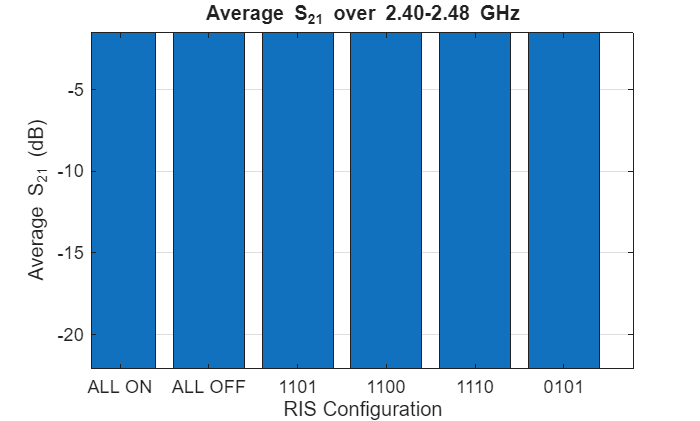



%% ============================================================
% PLOT AVERAGE S21
% =============================================================

figure('Color','w');

bar(Average_S21);

grid on;
box on;

set(gca, ...
    'XTick', 1:length(config_names), ...
    'XTickLabel', config_names, ...
    'FontSize', 11);

xlabel('RIS Configuration');
ylabel('Average S_{21} (dB)');

title('Average S_{21} over 2.40-2.48 GHz');